## Stability Regions of Explicit Runge—Kutta Methods with s=p

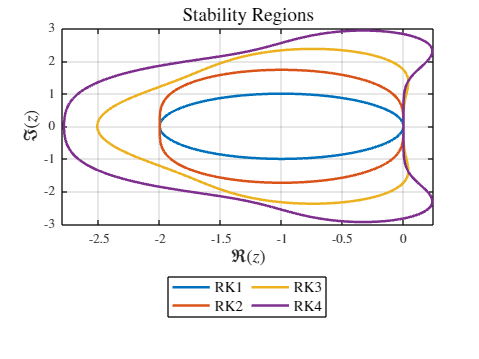

clear
close 
clc

set(groot,"defaultAxesTickLabelInterpreter","latex")
set(groot,"defaultTextInterpreter","latex")
set(groot,"defaultLegendInterpreter","latex")
set(groot, "defaultColorbarTickLabelInterpreter", "latex")

x = linspace(-2.8, 0.245, 400);
y = linspace(-3, 3, 400);
[X, Y] = meshgrid(x, y);
Z = X + 1i * Y; 

figure;
hold on;

colors = lines(4);

for n = 1 : 4
    R = zeros(size(Z));
    for k = 0 : n
        R = R + (Z .^ k) / factorial(k);
    end

    R_abs = abs(R);
    contour(X, Y, R_abs, [1 1], 'LineWidth', 2, 'LineColor', colors(n,:));
end

xlabel('$\Re(z)$', 'FontSize', 14);
ylabel('$\Im(z)$', 'FontSize', 14);
title('Stability Regions', 'FontSize', 15.5);
legend(compose("RK%i", 1:4), 'FontSize', 12, 'Location', 'southoutside', 'NumColumns', 2)
axis tight;  
grid on;
box on;
hold off;

% exportgraphics(gcf, "Stability_Regions.png", "Resolution", 900)

## Stability Region of Explicit Fifth Order Runge—Kutta—Butcher Method (s>p)

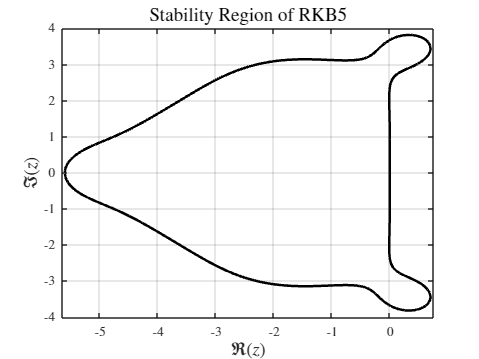

clear
close
clc

c_vector = [0 1/4 1/4 1/2 3/4 1] .';

A_matrix = [0 0 0 0 0 0;
            1/4 0 0 0 0 0;
            1/8 1/8 0 0 0 0;
            0 0 1/2 0 0 0;
            3/16 -3/8 3/8 9/16 0 0;
            -3/7 8/7 6/7 -12/7 8/7 0];

b_vector = [7/90 0 32/90 12/90 32/90 7/90] .';


x = linspace(-5.65, 0.75, 400);
y = linspace(-4, 4, 400);
[X, Y] = meshgrid(x, y);
Z = X + 1i * Y; 

I = eye(size(A_matrix));
one_vec = ones(size(c_vector));

syms z

R_sym = det(I - z * A_matrix + z * (one_vec * b_vector .')) / det(I - z * A_matrix);

R_coeffs = double(coeffs(R_sym));

R = zeros(size(Z));

for k = 0 : length(R_coeffs) - 1
    R = R + R_coeffs(k + 1) * (Z .^ k);
end

R_abs = abs(R);

figure;
contour(X, Y, R_abs, [1 1], '-k', 'LineWidth', 2);
xlabel('$\Re(z)$', 'FontSize', 14);
ylabel('$\Im(z)$', 'FontSize', 14);
axis tight;  
grid on;
box on;
title('Stability Region of RKB5', 'FontSize', 15.5)
% exportgraphics(gcf, "Stability_Region_RKB5.png", "Resolution", 900)

## Block of input data initialization. The Tamari Attractor

clear
clc
close

a = 1.013;
b = -0.011;
c = 0.02;	
d = 0.96;
e = 0.0;
fun = 0.01;
g = 1.0;
h = 0.05;
u = 0.05;

fun = @(t,x) [(x(1) - a * x(2)) * cos(x(3)) - b * x(2) * sin(x(3));
              (x(1) + c * x(2)) * sin(x(3)) + d * x(2) * cos(x(3));
               e + fun * x(3)+ g * atan((1 - u) / (1 - h) * x(1) * x(2))];

incond = [1 1 1];
timeint = [0 1000];
tau = 0.01;


s_stages = 7;
c_vector = [0 1/3 2/3 1/3 5/6 1/6 1]';
A_matrix = [zeros(1,s_stages);
            1/3 zeros(1,s_stages-1);
            0 2/3 zeros(1,s_stages-2);
            1/12 1/3 -1/12 zeros(1,s_stages-3);
            25/48 -55/24 35/48 15/8 zeros(1,s_stages-4);
            3/20 -11/24 -1/8 1/2 1/10 zeros(1,s_stages-5);
            -261/260 33/13 43/156 -118/39 32/195 80/39 zeros(1,s_stages-6)];
b_vector = [13/200 0 11/40 11/40 4/25 4/25 13/200]';

## Block of IVP solution

[t, xsol] = odeExplicitGeneral(c_vector,A_matrix,b_vector,fun,timeint,tau,incond)

t = 1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


xsol =     1.0000    1.0000    1.0000
    1.0000    1.0138    1.0080
    0.9999    1.0276    1.0160
    0.9997    1.0415    1.0242
    0.9995    1.0555    1.0324
    0.9992    1.0695    1.0406
    0.9989    1.0835    1.0489
    0.9985    1.0975    1.0573
    0.9980    1.1116    1.0658
    0.9974    1.1257    1.0743


## Block of visualization of the obtained results

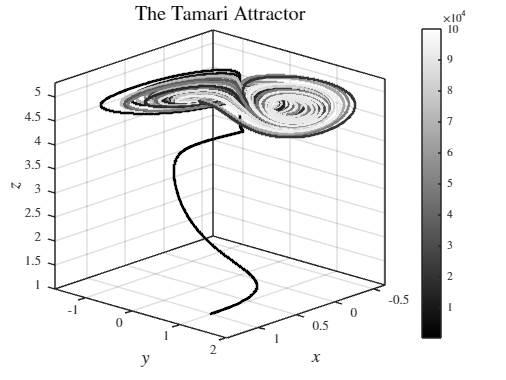

figure();
scatter3(xsol(:,1), xsol(:,2), xsol(:,3), 4,1:length(xsol(:,1)),'filled');
colormap gray;
colorbar;
axis tight;
grid on;
box on;
view([-227.35 19.42])
xlabel('$x$','FontSize',14 );
ylabel('$y$','FontSize',14 );
zlabel('$z$','FontSize',14 );
title('The Tamari Attractor','FontSize',16);

## **Block of exporting the obtained results**

% exportgraphics(gcf,"The_Tamari_Attractor.pdf", "ContentType","vector")

% exportgraphics(gcf,"The_Tamari_Attractor.png", "Resolution", 1200)

% save("results.mat")